DataStruct = load('data.mat');
Data = DataStruct.data;
labels = DataStruct.class;

feature1 = Data(:,1);

h = chi2gof(feature1);
h

h = 1

disp('h = 1 means chi-square test rejects null  hypothesis at the 5% significance level, same for other testings');

h = 1 means chi-square test rejects null  hypothesis at the 5% significance level, same for other testings


h1 = adtest(feature1);

h1

h1 = logical
   1


h2 = adtest(feature1);

h2

h2 = logical
   1


h3 = kstest(feature1);
h3

h3 = logical
   1


% find indices of each class
class1_Idx = find(labels==0);
class2_Idx = find(labels==1);

class1_data = Data(class1_Idx,:);
class2_data = Data(class2_Idx,:);

class1_labels = ones(length(class1_Idx),1);
class2_labels = zeros(length(class2_Idx),1);

% stratified split
[train_set, test_set, train_labels, test_labels] = stratified_split(class1_data, class2_data, class1_labels, class2_labels, 0.25, 2000);

test_feature1 = test_set(:,1);
train_feature1 = train_set(:,1);
class1_testIdx = find(test_labels==0);
class2_testIdx = find(test_labels==1);

% Bayes classification feature 1 
EmGmm(train_feature1, test_feature1, class1_testIdx, class2_testIdx, 2);

20 iterations, log-likelihood = -3416.23
Bayes Confusion matrix : 
        1487        1456
          44          13

Bayes error rate: 
    50



test_feature2 = test_set(:,2);
train_feature2 = train_set(:,2);
% Bayes classification feature 2 
EmGmm(train_feature2, test_feature2, class1_testIdx, class2_testIdx, 2);

46 iterations, log-likelihood = -3088.13
Bayes Confusion matrix : 
          91          56
        1444        1409

Bayes error rate: 
    50



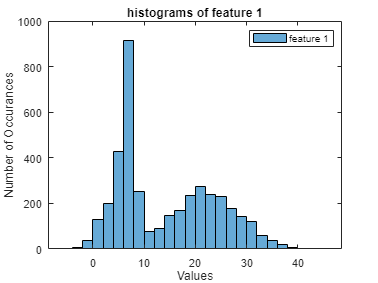

% observe all features
feature2 = Data(:,2);
feature3 = Data(:,3);
feature4 = Data(:,4);
feature5 = Data(:,5);
feature6 = Data(:,6);

histogram(feature1);
legend("feature 1");
title('histograms of feature 1');
xlabel('Values');
ylabel('Number of Occurances');

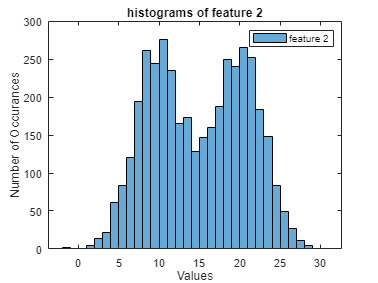


histogram(feature2);
legend("feature 2");
title('histograms of feature 2');
xlabel('Values');
ylabel('Number of Occurances');

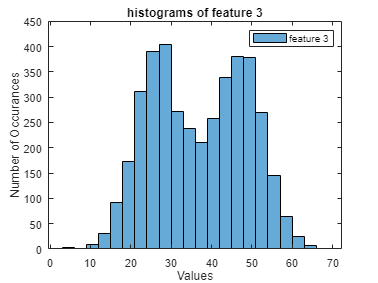


histogram(feature3);
legend("feature 3");
title('histograms of feature 3');
xlabel('Values');
ylabel('Number of Occurances');

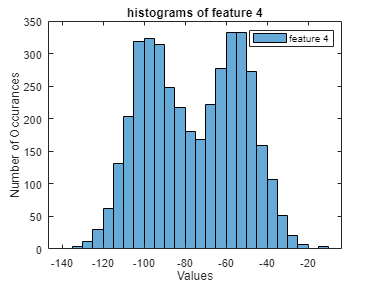


histogram(feature4);
legend("feature 4");
title('histograms of feature 4');
xlabel('Values');
ylabel('Number of Occurances');

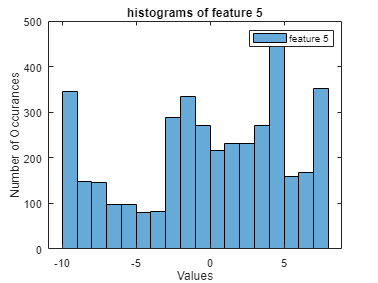


histogram(feature5);
legend("feature 5");
title('histograms of feature 5');
xlabel('Values');
ylabel('Number of Occurances');

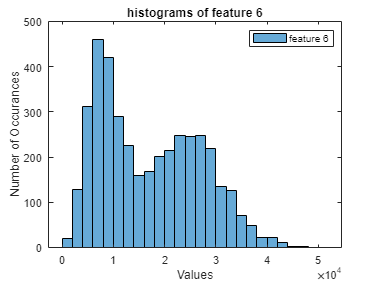


histogram(feature6);
legend("feature 6");
title('histograms of feature 6');
xlabel('Values');
ylabel('Number of Occurances');


% scale to [-1 1], since scale is dfferent
norm_feature1 = MinMaxNorm(feature1);
norm_feature2 = MinMaxNorm(feature2);
norm_feature3 = MinMaxNorm(feature3);
norm_feature4 = MinMaxNorm(feature4);
norm_feature5 = MinMaxNorm(feature5);
norm_feature6 = MinMaxNorm(feature6);

norm_Data = [norm_feature1 norm_feature2 norm_feature3 norm_feature4 norm_feature5 norm_feature6];
norm_class1_data = norm_Data(class1_Idx,:);
norm_class2_data = norm_Data(class2_Idx,:);

% stratified split on normalized data
[norm_train_set, norm_test_set, norm_train_labels, norm_test_labels] = stratified_split(norm_class1_data, norm_class2_data, class1_labels, class2_labels, 0.25, 2000);

norm_test_feature1 = norm_test_set(:,1);
norm_train_feature1 = norm_train_set(:,1);
norm_class1_testIdx = find(norm_test_labels==0);
norm_class2_testIdx = find(norm_test_labels==1);

% Bayes classification normalized feature 1 
EmGmm(norm_train_feature1, norm_test_feature1, norm_class1_testIdx, norm_class2_testIdx, 2);

26 iterations, log-likelihood = -224.248
Bayes Confusion matrix : 
        1488        1455
          45          12

Bayes error rate: 
    50



% normalized feature 2
EmGmm(norm_train_set(:,2), norm_test_set(:,2), norm_class1_testIdx, norm_class2_testIdx, 2);

47 iterations, log-likelihood = -343.08
Bayes Confusion matrix : 
        1398        1456
          44         102

Bayes error rate: 
    50



% normalized feature 3
EmGmm(norm_train_set(:,3), norm_test_set(:,3), norm_class1_testIdx, norm_class2_testIdx, 2);

56 iterations, log-likelihood = -343.08
Bayes Confusion matrix : 
         102          44
        1456        1398

Bayes error rate: 
    50



% normalized feature 4
EmGmm(norm_train_set(:,4), norm_test_set(:,4), norm_class1_testIdx, norm_class2_testIdx, 2);

36 iterations, log-likelihood = -343.08
Bayes Confusion matrix : 
         102          44
        1456        1398

Bayes error rate: 
    50



% normalized feature 5
EmGmm(norm_train_set(:,5), norm_test_set(:,5), norm_class1_testIdx, norm_class2_testIdx, 2);

93 iterations, log-likelihood = -826.1
Bayes Confusion matrix : 
   923   621
   879   577

Bayes error rate: 
    50



% normalized feature 6
EmGmm(norm_train_set(:,6), norm_test_set(:,6), norm_class1_testIdx, norm_class2_testIdx, 2);

30 iterations, log-likelihood = -323.543
Bayes Confusion matrix : 
         245          14
        1486        1255

Bayes error rate: 
    50



net = patternnet(10);
net.inputs{1}.processFcns;
net.trainParam.showWindow = false;
[net,tr] = train(net,norm_train_set.' ,norm_train_labels.');
test_pred = net(norm_test_set.');
perf = perform(net,norm_test_labels.',test_pred);
nn_diff = sum(abs(round(test_pred.')-test_labels));

% calculate accuracy 
nn_acc = (3000-nn_diff)/3000;

disp('NN error rate: ');

NN error rate: 


disp(100-nn_acc*100);

    0.3000



corr_feature_1_2 = corrcoef(norm_feature1,norm_feature2);
corr_feature_1_2 =corr_feature_1_2(1,2)

corr_feature_1_2 = 0.7493


corr_feature_1_3 = corrcoef(norm_feature1,norm_feature3);
corr_feature_1_3 =corr_feature_1_3(1,2)

corr_feature_1_3 = 0.7493


corr_feature_1_4 = corrcoef(norm_feature1,norm_feature4);
corr_feature_1_4 =corr_feature_1_4(1,2)

corr_feature_1_4 = -0.7493


corr_feature_1_5 = corrcoef(norm_feature1,norm_feature5);
corr_feature_1_5 =corr_feature_1_5(1,2)

corr_feature_1_5 = 0.0313


corr_feature_1_6 = corrcoef(norm_feature1,norm_feature6);
corr_feature_1_6 =corr_feature_1_6(1,2)

corr_feature_1_6 = 0.7423


corr_feature_2_3 = corrcoef(norm_feature3,norm_feature2);
corr_feature_2_3 =corr_feature_2_3(1,2)

corr_feature_2_3 = 1


corr_feature_2_4 = corrcoef(norm_feature4,norm_feature2);
corr_feature_2_4 =corr_feature_2_4(1,2)

corr_feature_2_4 = -1


corr_feature_2_5 = corrcoef(norm_feature5,norm_feature2);
corr_feature_2_5 =corr_feature_2_5(1,2)

corr_feature_2_5 = 0.0169


corr_feature_2_6 = corrcoef(norm_feature6,norm_feature2);
corr_feature_2_6 =corr_feature_2_6(1,2)

corr_feature_2_6 = 0.9893


corr_feature_3_4 = corrcoef(norm_feature3,norm_feature4);
corr_feature_3_4 =corr_feature_3_4(1,2)

corr_feature_3_4 = -1.0000


corr_feature_3_5 = corrcoef(norm_feature3,norm_feature5);
corr_feature_3_5 =corr_feature_3_5(1,2)

corr_feature_3_5 = 0.0169


corr_feature_3_6 = corrcoef(norm_feature3,norm_feature6);
corr_feature_3_6 =corr_feature_3_6(1,2)

corr_feature_3_6 = 0.9893


corr_feature_4_5 = corrcoef(norm_feature4,norm_feature5);
corr_feature_4_5 =corr_feature_4_5(1,2)

corr_feature_4_5 = -0.0169


corr_feature_4_6 = corrcoef(norm_feature4,norm_feature6);
corr_feature_4_6 =corr_feature_4_6(1,2)

corr_feature_4_6 = -0.9893


corr_feature_5_6 = corrcoef(norm_feature5,norm_feature6);
corr_feature_5_6 =corr_feature_5_6(1,2)

corr_feature_5_6 = 0.0178

The features are not statistically independent. We can see that feature 2 and feature 3 have perfect positive correlation. And feature 2&3 have perfect negative correlation with feature 4. It means they are duplicated. Apart from that, we can see that many features have high correlation with feature 6. Additionally, feature 1 have the same magnitude of relatively high correlation with feature2,3&4.

Discuss the differences and distinctions between the meanings of the terms statistical correlation and mutual information. Can features measurements assessed to be uncorrelated still share mutual information?

Answer: Statistical correlation is a measure of linear relationship between 2 random variables, more specifically, it measure how does B change when A changes. Statistical correlation ranges from -1 to 1, with 1 being perfectly positive correlation, -1 being perfectly negative correlation, and 0 being no correlation. On the other hand, mutual information is a measure of how much knowing A helps with knowing B, i.e., how much entropy/uncertainty is reduced in order to know B if we know A, and vice versa, as mutual information is symmetric: I(A;B) = H(A) - H(A|B) = H(B) - H(B|A) = I(B;A). Mutual information >= 0, if mutual information = 0, that means knowing B doesn't help knowing A, and vice versa. Therefore, it is possible for features to be uncorrelated but still share mutual information when the features are not linearly dependent but still having non-linear relationships.

Features with high correlation and/or mutual information is detrimental to the performance of classifiers. This is because features with high correlation and/or mutual information suggests duplicate information, and thus overall there are less useful information (than same number of features with little/no correlation and/or mutual information). This is also known as multicollinearity, and as a result, it is difficult to identify each feature's effect on the target label. Additionally because of the redundant dimentions, it requires exponentially high computing power, which is known as curse of dimentionality. 

Parametric classifiers such as Bayes are more sensitive to the impact. This is because parametric classifiers rely on the prior specification of a set of parameters that describe the data distribution. Therefore poor features selection has more effect on them than non-parametric classifiers.

Methods available in the data analysis literature that could be used to help identify whether non-linear relationships may exist between feature measurements.

- Feature selection using p-value. P-value suggests the probability of observation ocuuring assuming null hypothesis is true. We can try to remove one feature at a time and measure the p-value each time. If some features have high correlations, then removing one of them will cause p-values to exceed its threshold. This method is suggested in the blog Feature selection: Correlation and P-value by Vishal R.

- Plots/Visualization. We can scatter plot features against each other and visualize if there are high correlations. 

- Calulating the correlations like we did in question 6.

- Intrinsic feature selection methods. Intrinsic feature selection methods refer to the model/algorithm being able to select features that optimize the performance. Decision tree and random forest are examples of intrinsic feature selection methods. Under each internal node of the tree, the child feature is the one with lowest entropy. This method can help avoid features with high correlation because in each layer only one feature is selected.

- Dimentionality reduction. Although this is not a technique that "identifies" features with high correlation, it can help avoid the problem by reducing the dimentionality.

Functions

% stratified split functions

function [train, test, train_y, test_y]=stratified_split(c1,c2, y1, y2, ratio, m)
    % generate random indices
    rand_idx = randperm(m);
    train_idx = rand_idx(1:round(ratio*m));
    test_idx = rand_idx(round(ratio*m)+1:end);
    % equal split with each class
    c1_train = c1(train_idx,:);
    c1_test = c1(test_idx,:);
    c2_train = c2(train_idx,:);
    c2_test = c2(test_idx,:);
    train_y1 = y1(train_idx);
    test_y1 = y1(test_idx);
    train_y2 = y2(train_idx);
    test_y2 = y2(test_idx);
    train = [c1_train;c2_train];
    test = [c1_test;c2_test];
    train_y = [train_y1;train_y2];
    test_y = [test_y1;test_y2];
end

function EmGmm(train, test, c1_testIdx, c2_testIdx, numCom)
    % fit gmm model
    gmm = fitgmdist(train,numCom,'Options',statset('Display','final'));

    % predict using probabilities
    P = posterior(gmm, test);
    [pred, predIdx] = max(P,[],2);
    predIdx = predIdx - 1;
    
    % compare predictions and true labels
    diff1_idx = ismember(find(predIdx==0),find(c1_testIdx));
    diff2_idx = ismember(find(predIdx==1),c2_testIdx);
    
    % calculate accuracy 
    acc = (length(find(diff1_idx))+length(find(diff2_idx)))/3000;
    
    % construct confusion matrix
    TP = length(find(diff1_idx));
    TN = length(find(diff2_idx));
    FP = length(find(~diff1_idx));
    FN = length(find(~diff2_idx));
    Confusion = [TP FN;FP TN];
    
    disp('Bayes Confusion matrix : ');
    disp(Confusion);
    disp('Bayes error rate: ');
    disp(100-acc*100);
end

% scale range to [-1 1]
function scaled = MinMaxNorm(data)
    scaled = 2.*(data - min(data))./(max(data) - min(data))-1;
end

% function for discriminant analysis
function gi = Discriminant(x, mu, sigma, prob)
    % caluclate terms for discriminat function separatly
    inv_sigma = inv(sigma);
    cap_w = -1/2*inv_sigma;
    w = inv_sigma*mu;
    w_const = -1/2*(mu.')*inv_sigma*mu - 1/2*log(det(sigma)) + log(prob);
    
    % create discriminant function
    gi = dot((x*cap_w).',x.') + (w.')*x.' + w_const;
end
